# Sensitivity analysis - Simple case with Tikhonov regularization

#### Author: Luis Fabregas

In this tutorial we will discuss a simpe example of sensitivity analysis of Tikhonov regularization results. The example will cover how to define, prepare and launch the sensitivity analysis in terms of the influence of noise and selection methods on the regularization.

## Simulate the data

Let's start by generating some data.

%Prepare signal components
t = linspace(-0.4,3.5,200);
r = time2dist(t);
P = rd_twogaussian(r,[3 0.3 3.5 0.4 0.6]);
B = td_strexp(t,[0.04,2.8]);
lam = 0.32;

%Simulate signal
V = dipolarsignal(t,r,P,'moddepth',lam,'background',B,'noiselevel',0.01);

## Regularization fit

For the sake of simplicity, in this tutorial we will assume that we know the background exactly. Our first step is to generate the proper dipolar kernel.

%Generate dipolar kernel with background
KB = dipolarkernel(t,r,lam,B);

We now have all the elements required to fit our distance distribution via regularization. We will use the AIC to select the regularization parameter int he Tikhonov regularization.

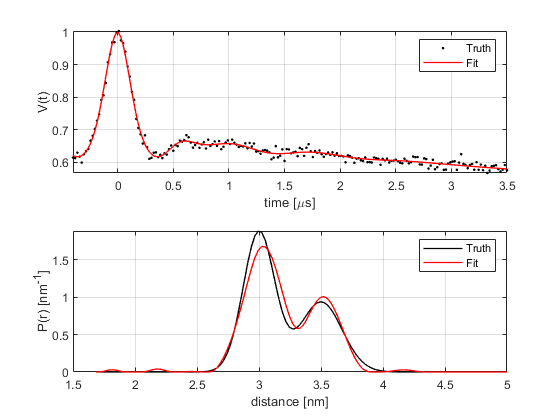

%Fit data via regularization
Pfit = fitregmodel(V,KB,r,'tikh','aic');
%Obtain time-domain fit
Vfit = KB*Pfit;

%Plot the fit results
subplot(211)
plot(t,V,'k.',t,Vfit,'r','LineWidth',1)
grid on, axis tight,box on
xlabel('time [\mus]')
ylabel('V(t)')
legend('Truth','Fit')

subplot(212)
plot(r,P,'k',r,Pfit,'r','LineWidth',1)
grid on, axis tight,box on
xlim([1.5 5])
xlabel('distance [nm]')
ylabel('P(r) [nm^{-1}]')
legend('Truth','Fit')

## Sensitivity analysis

Now that we have the fit of our data, let's analyze the inlfuence of certain factors on our results. For instance, let's condier the influence of the method employed for the selection of the regularization parameter as well as the one from noise. Since the noise in the sample cannot be changed once measured (in experimental data) we will analyze the influence of added noise on our results.

We just need to define our analysis function (see below) and the factors and their realizations to analyze. The function will return the median, as well as upper/lower bounds of the distance distribution.

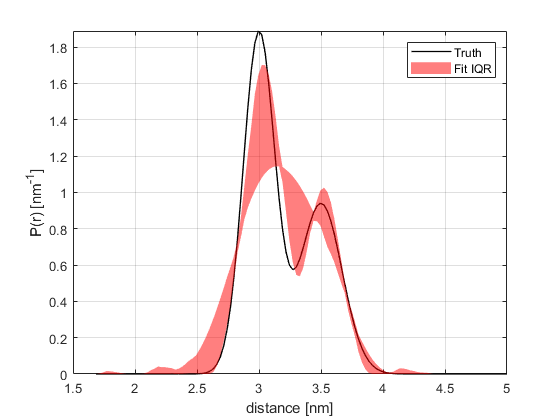

%Define the factors
factors.selection = {'aic','aicc','bic'};
factors.addednoiselevel = linspace(0,0.02,3);

%Launch the sensitivity analysis
fcn = @(factors) myanalysis(factors,V,KB,r,t);
[Pmed,Pup,Plo] = sensitivan(fcn,factors);

%Plot sentivity analysis results
clf,hold on
plot(r,P,'k','LineWidth',1)
fill([r fliplr(r)],[Pup fliplr(Plo)],'r','FaceAlpha',0.5,'LineStyle','none')
grid on, axis tight,box on
xlim([1.5 5])
xlabel('distance [nm]')
ylabel('P(r) [nm^{-1}]')
legend('Truth','Fit IQR')

The analysis function must be defined at the end of the script in order to be able to be used as a function. The `sensitivan` function requires a function which only accepts the `factors` structure as an input. However, we can define the function to accept as many inputs as necessary. The function inputs can be adapted by defining a new function handle (e.g. `fcn` above).

Our analysis function will just take the signal, add some noise of a given noise level and then regularize using one of the given selection methods. 

function Pfit = myanalysis(factors,V,KB,r,t)

%Extract current factors
selection = factors.selection;
addednoiselevel = factors.addednoiselevel;

%Add noise with varying level
V = V + whitegaussnoise(t,addednoiselevel);

%Do regularization with varying selection method
Pfit = fitregmodel(V,KB,r,'tikh',selection);
end